# VERIFICATION OF SUPER-POSITION THEOREM

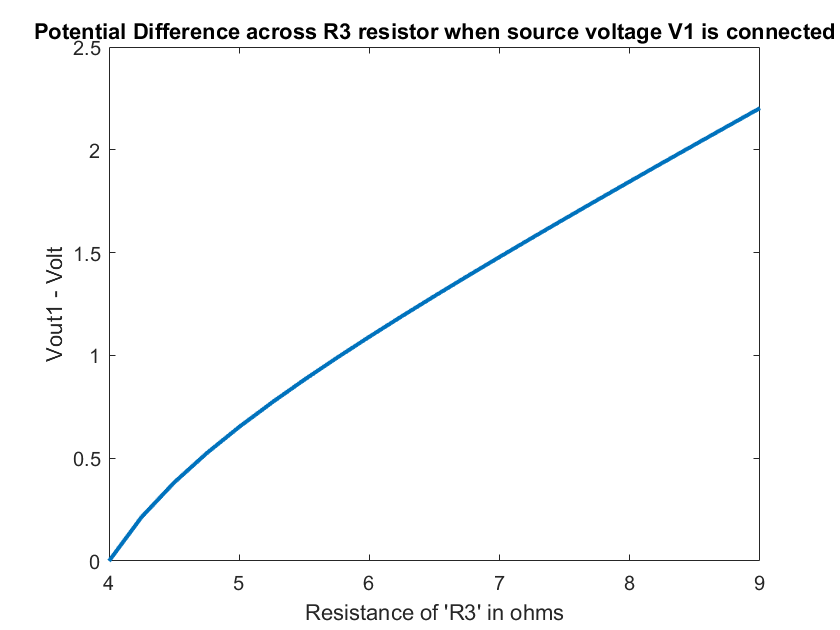

clc;
clear all;
close all;

% Resistance Values
R1 = 0:0.25:5;
R2 = 2:0.25:7;
R3 = 4:0.25:9;

% Source Voltages
V1 = 0:0.25:5;
V2 = 5:-0.25:0;

% With source voltage V1
R_TH = R1.*R2 ./ (R1 + R2);
I2 = (V1) ./ (R1 + R2);
V_ab_1 =  V1 - I2.*R1;
IR3_1 = V_ab_1 ./ (R3 + R_TH);
Vout1 = IR3_1 .* R3;
figure
plot(R3,Vout1,"LineWidth",2)
title("Potential Difference across R3 resistor when source voltage V1 is connected")
xlabel("Resistance of 'R3' in ohms")
ylabel("Vout1 - Volt")

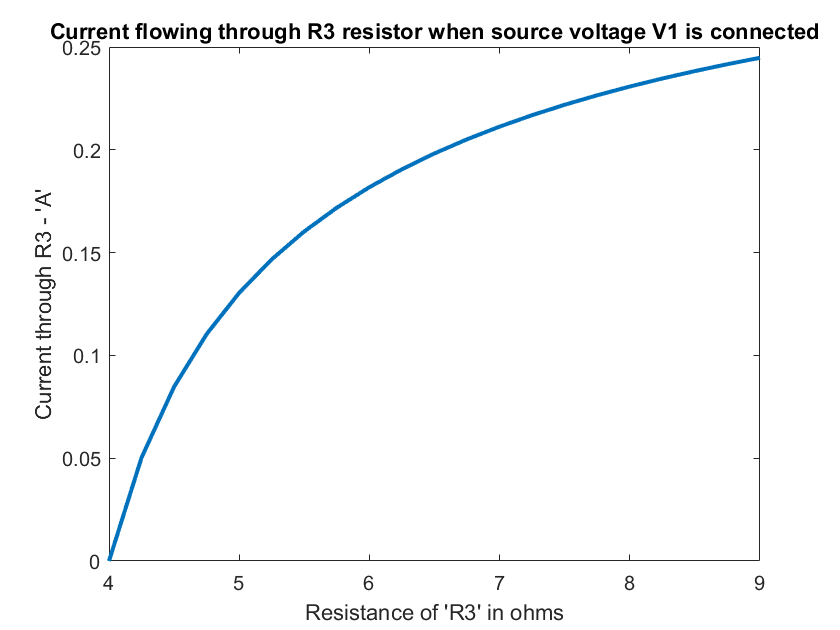

plot(R3,IR3_1,"LineWidth",2)
title("Current flowing through R3 resistor when source voltage V1 is connected")
xlabel("Resistance of 'R3' in ohms")
ylabel("Current through R3 - 'A'")

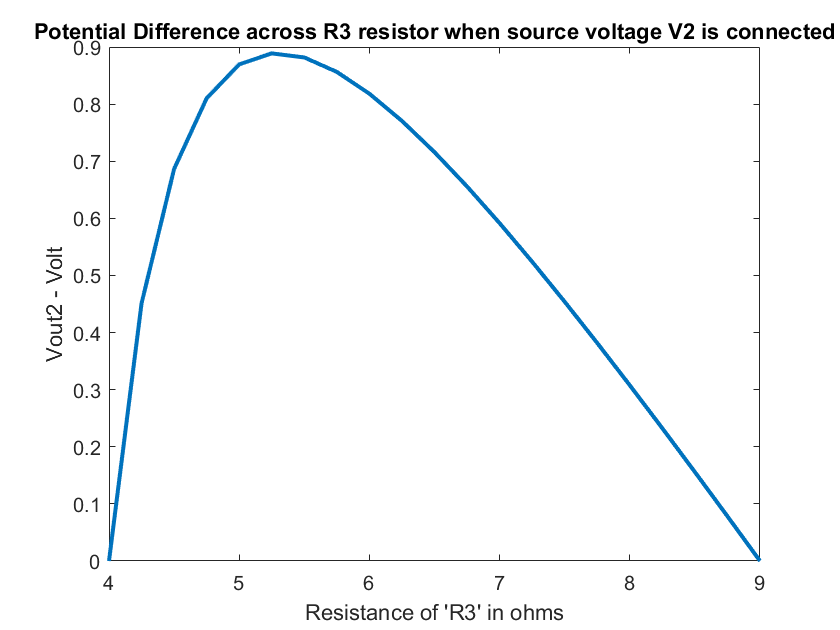


% With source voltage V2
R_TH = R1.*R2 ./ (R1 + R2);
I3 = (V2) ./ (R1 + R2);
V_ab_2 =  V2 - I3.*R2;
IR3_2 = V_ab_2 ./ (R3 + R_TH);
Vout2 = IR3_2 .* R3;
figure
plot(R3,Vout2,"LineWidth",2)
title("Potential Difference across R3 resistor when source voltage V2 is connected")
xlabel("Resistance of 'R3' in ohms")
ylabel("Vout2 - Volt")

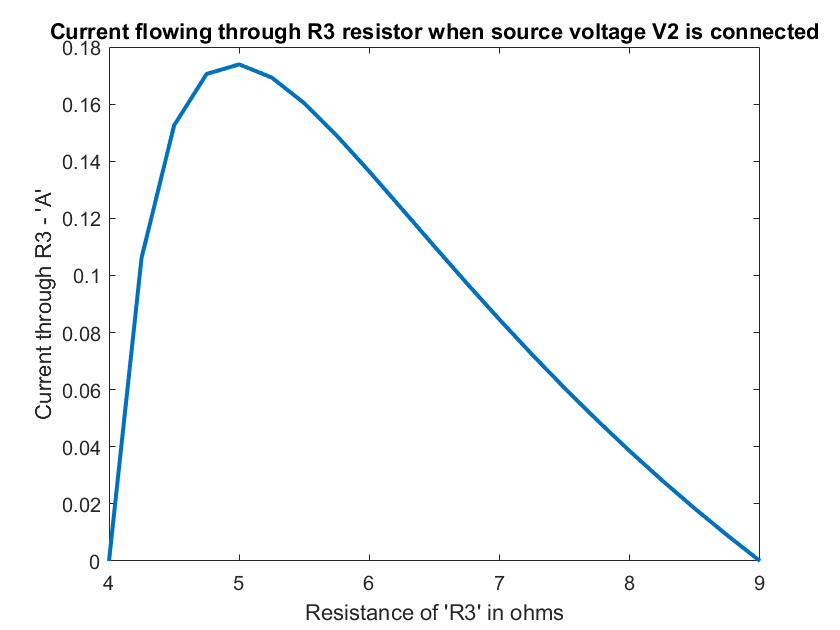

plot(R3,IR3_2,"LineWidth",2)
title("Current flowing through R3 resistor when source voltage V2 is connected")
xlabel("Resistance of 'R3' in ohms")
ylabel("Current through R3 - 'A'")

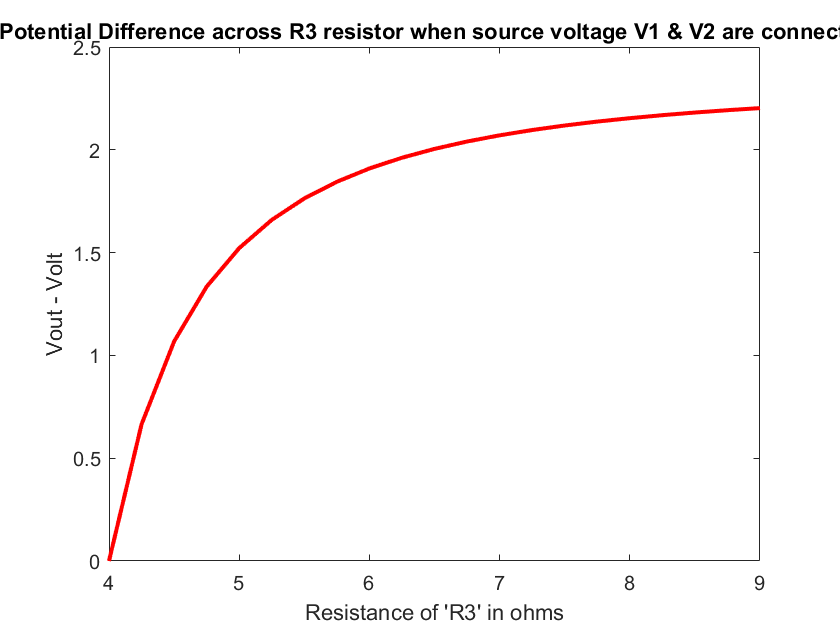

% Summing up both potentials Vout1 and Vout2 to get Vout
% Summing up current flowing through Resistor R3, found above, IR3_1 & IR3_2
Vout = Vout1 + Vout2;
IR3 = IR3_1 + IR3_2;
plot(R3,Vout,"LineWidth",2,"Color",'r')
title("Potential Difference across R3 resistor when source voltage V1 & V2 are connected")
xlabel("Resistance of 'R3' in ohms")
ylabel("Vout - Volt")

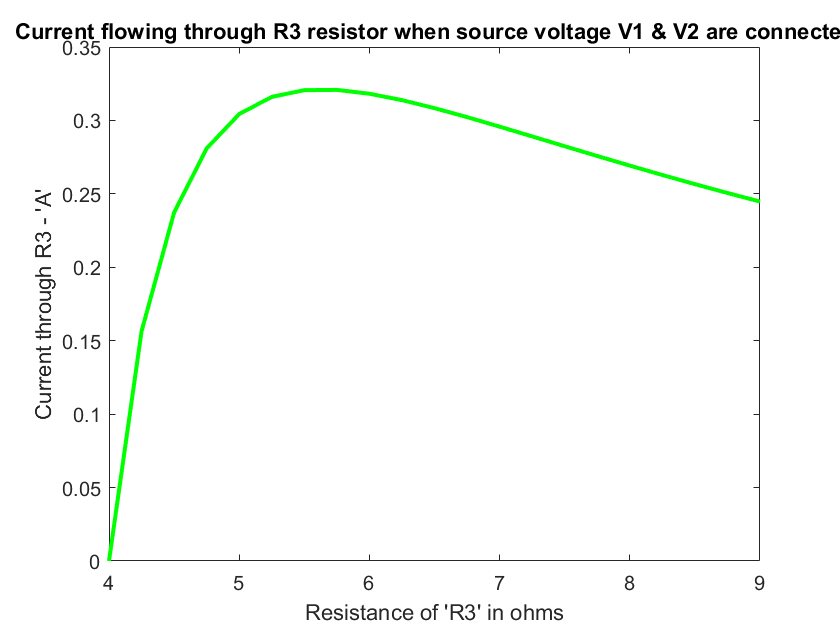

plot(R3,IR3,"LineWidth",2,"Color",'green')
title("Current flowing through R3 resistor when source voltage V1 & V2 are connected")
xlabel("Resistance of 'R3' in ohms")
ylabel("Current through R3 - 'A'")

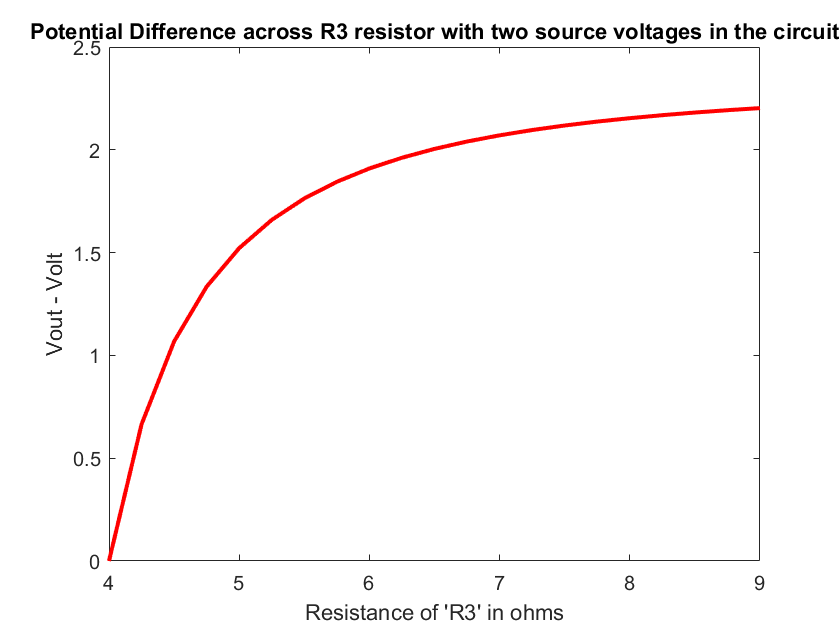


% With source voltageS V1 and V2
R_TH = R1.*R2 ./ (R1 + R2);
I1 = (V1 - V2) ./ (R1 + R2);
V_ab =  V1 - I1.*R1;
IR3 = V_ab ./ (R3 +R_TH);
Vout = IR3 .* R3;
plot(R3,Vout,"LineWidth",2,"Color",'r')
title("Potential Difference across R3 resistor with two source voltages in the circuit")
xlabel("Resistance of 'R3' in ohms")
ylabel("Vout - Volt")

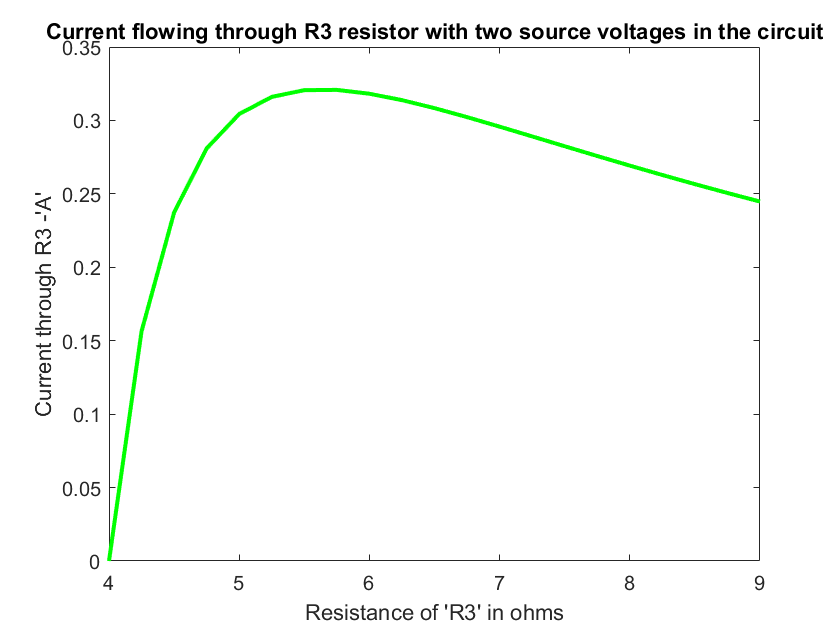

plot(R3,IR3,"LineWidth",2,"Color",'green')
title("Current flowing through R3 resistor with two source voltages in the circuit")
xlabel("Resistance of 'R3' in ohms")
ylabel("Current through R3 -'A'")